clear all; clc;
%生成白光干涉信号
%显示光谱信息
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency = (spectrum{:,1})';
spectrum_intensity = (spectrum{:,2})';
disp("全部光谱信息");

全部光谱信息


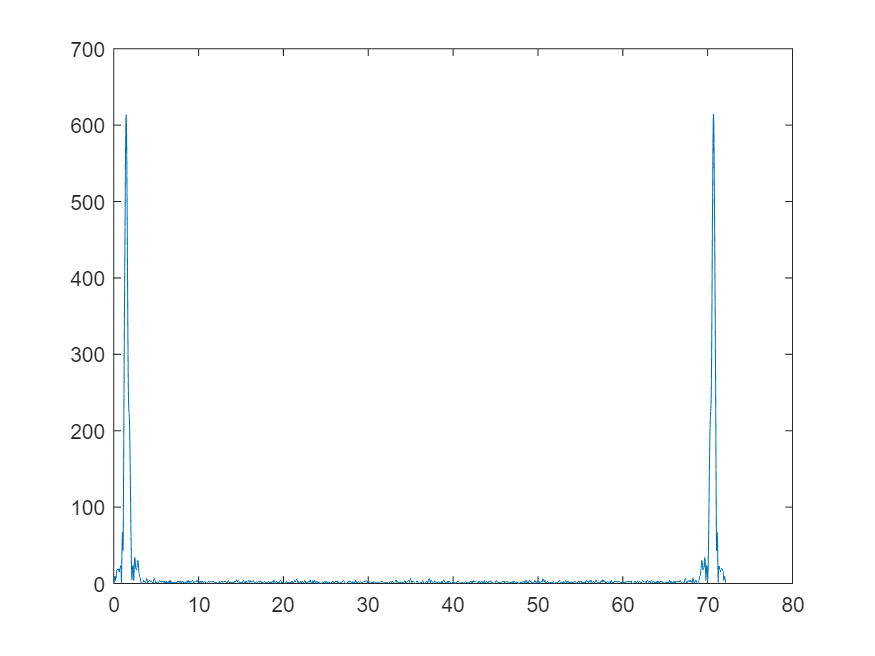

plot(spectrum_frequency,spectrum_intensity)

%找出探测器对应的光谱，这里假设是1.1-2.1
[Min, indix_min] = min(abs(spectrum_frequency-1.1));
[Max, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency = spectrum_frequency(indix_min:indix_max);
spectrum_intensity = spectrum_intensity(indix_min:indix_max);
disp("需要的光谱信息");

需要的光谱信息


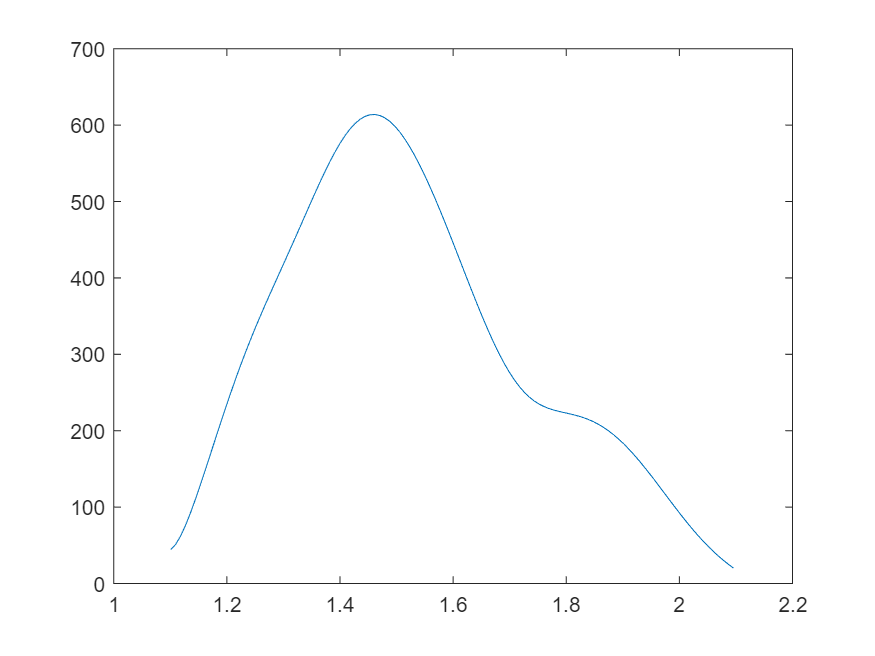

plot(spectrum_frequency,spectrum_intensity);

%生成白光干涉信号
z0 = 10;    %单位为微米
N = 2^14;
z = linspace(-10,30,N);
interference_signal = zeros(1,length(z));
for i = 1:length(z)
    for n = 1:length(spectrum_frequency)
        interference_signal(i) = interference_signal(i)+spectrum_intensity(n)./2+...
        spectrum_intensity(n)/2*cos(4*pi*(z(i)-z0)*spectrum_frequency(n));
    end
end
disp("生成的白光干涉信号");

生成的白光干涉信号


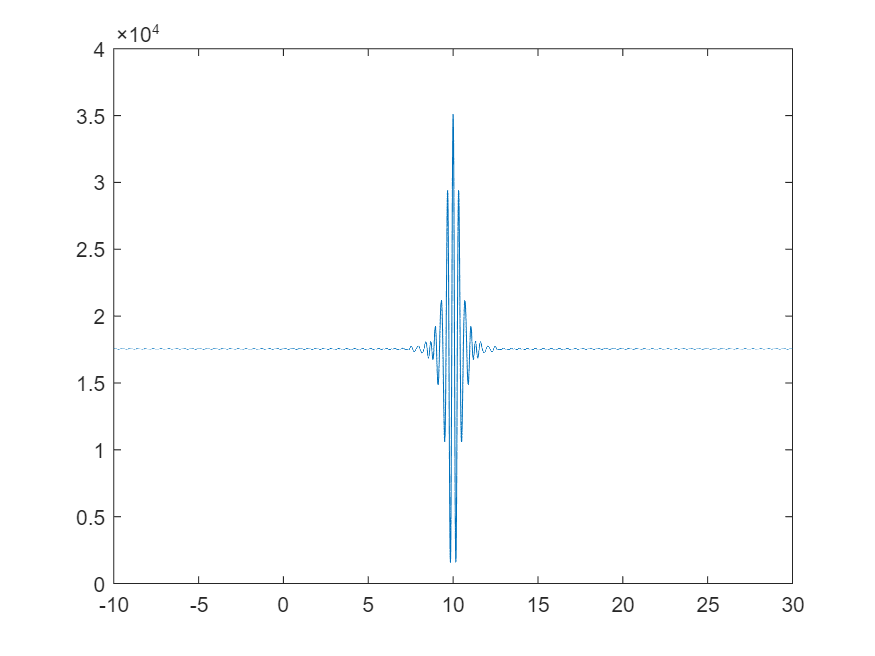

plot(z,interference_signal);

%加入色散
%色散公式
lambda = 1./spectrum_frequency;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./(lambda.^2-103.560653)+...
        (0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));
%折射率曲线
disp("折射率曲线");

折射率曲线


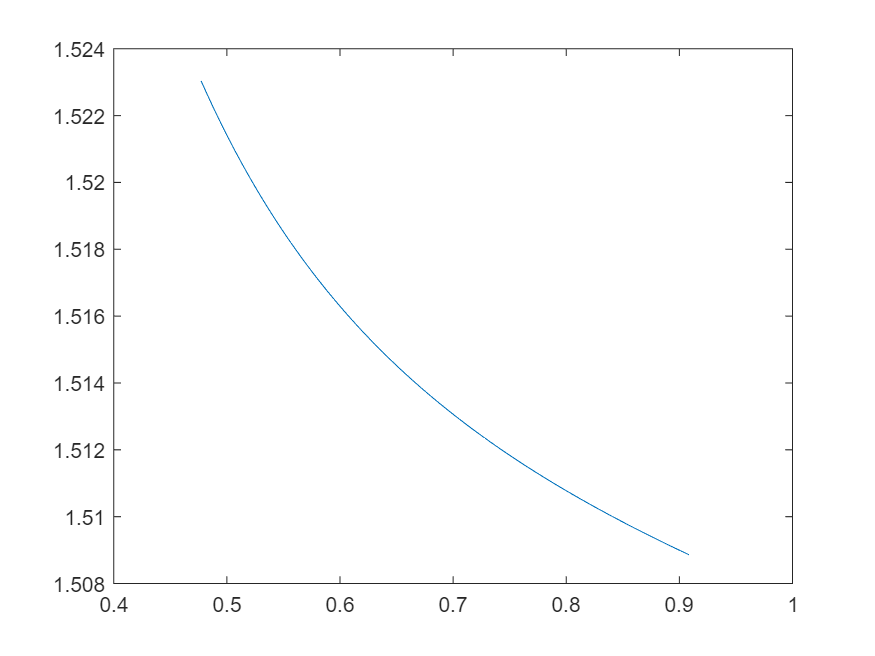

plot(lambda,index);

%色散
lEpsilon = 20 %单位为微米

lEpsilon = 20

interference_signal = zeros(1,length(z));
for i = 1:length(z)
    for n = 1:length(spectrum_frequency)
        interference_signal(i) = interference_signal(i)+spectrum_intensity(n)/2+...
        spectrum_intensity(n)/2*cos(4*pi*(z(i)-z0)*spectrum_frequency(n)+...
        4*pi*(index(n)-1)*spectrum_frequency(n)*lEpsilon);
    end
end
disp("生成有色散的白光干涉信号");

生成有色散的白光干涉信号


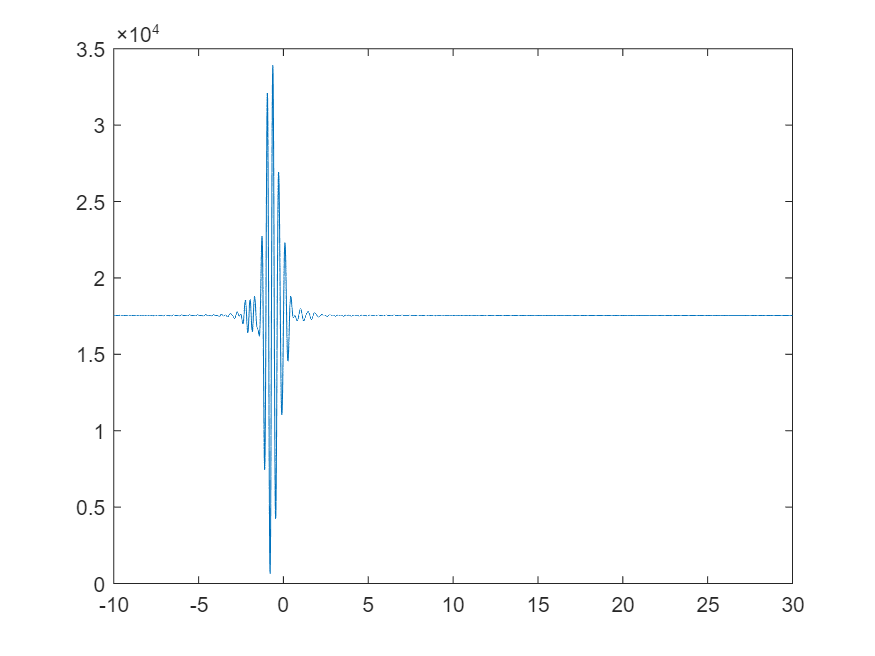

plot(z,interference_signal);

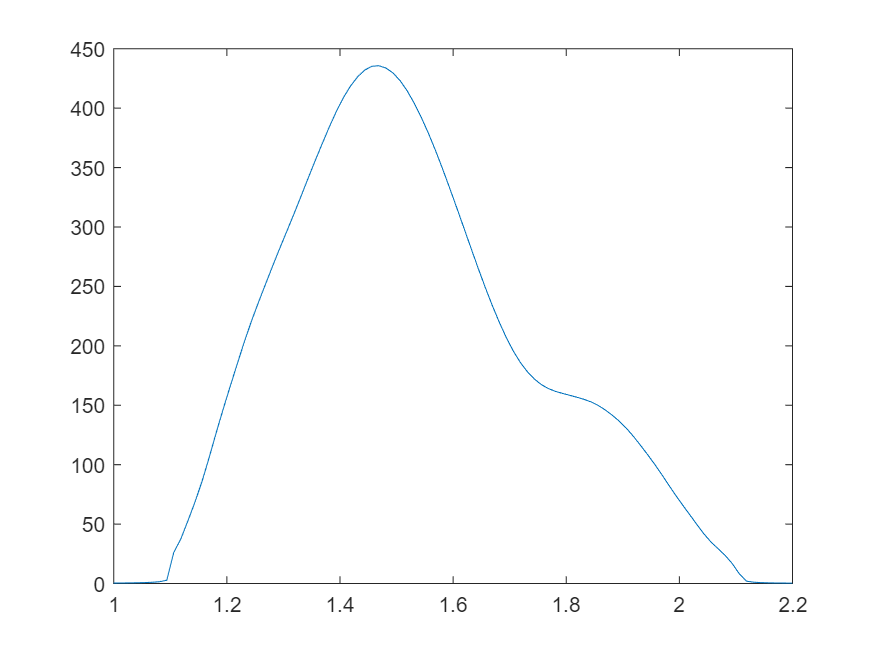

%傅里叶变换
deltaZ = ((z(end)-z(1))/(N-1));
deltaSigma = 1/(2*deltaZ*N);
sigma = (0:N-1)*deltaSigma;
f_interference_signal = fft(interference_signal);
%fis:f_interference_signal
abs_fis = abs(f_interference_signal);
ang_fis = angle(f_interference_signal);
% abs_fis(1) = 0;%abs_fis(1)/N;
abs_fis(2:end) = 2*abs_fis(2:end)/N;
abs_fis = fftshift(abs_fis);
ang_fis = fftshift(ang_fis);
plot(sigma-sigma(end)/2,abs_fis);
xlim([1 2.2]);

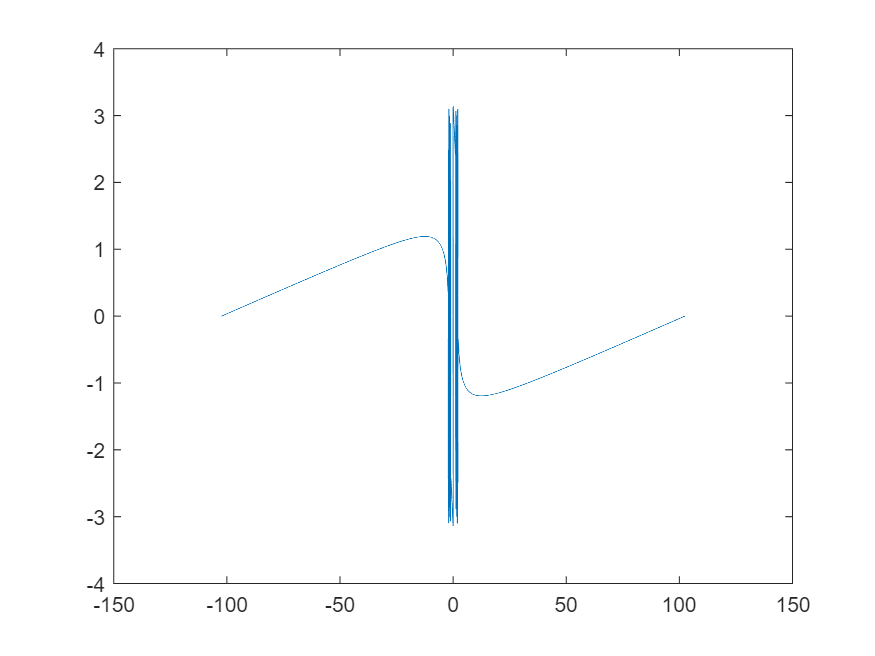

plot(sigma-sigma(end)/2,ang_fis);